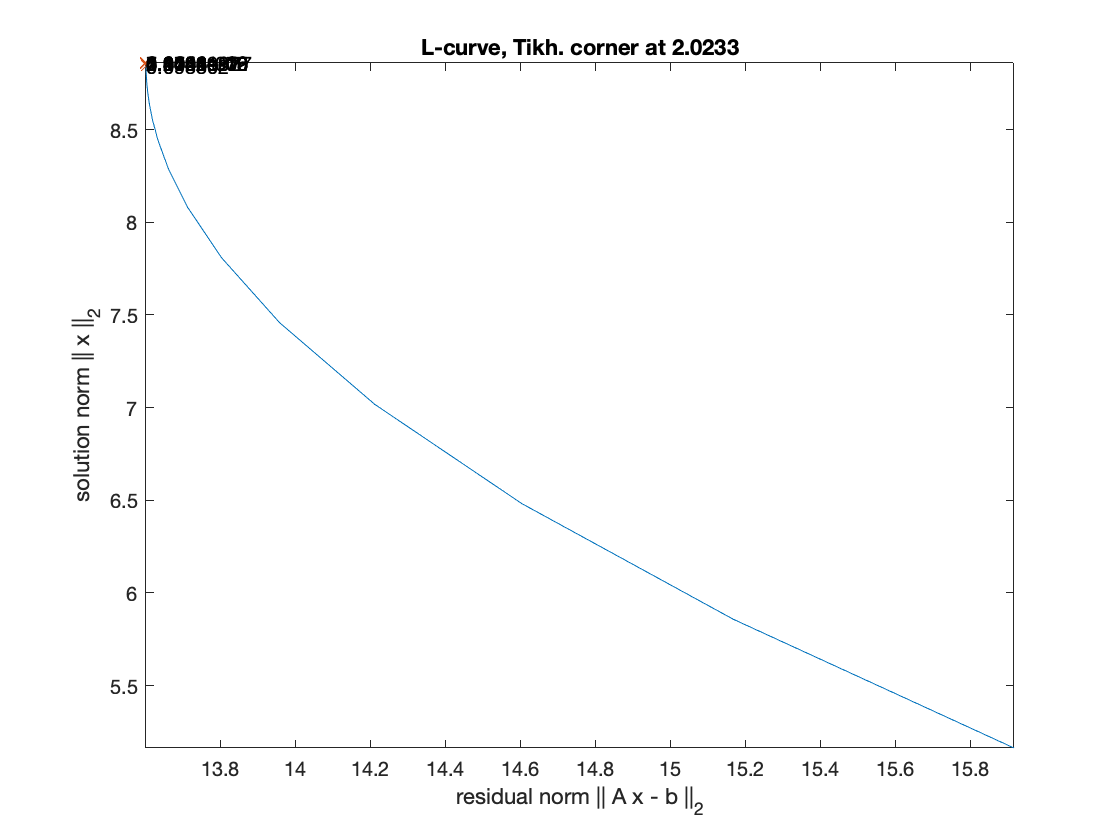

clear
clc
addpath('/Users/mathuser/Documents/PHD/Spring_2022/Inverse Theory/regu')

global Jacb2; global funy;
global t ; global Yt; global sigma;

Jacb2 = @(m) [exp(m(2).*t) m(1)*t.*exp(m(2)*t)];

funy = @(m) (m(1)*exp(m(2)*t) - Yt);

t = [1,2,4,5,8]';
Yt = [3.2939,4.2699,7.1749,9.3008,20.259]';
sigma = 0.15;

ml = length(Yt);

% Get the singular values for the matrix G
m0 = [0;0]; % initial parameter estimates
G = Jacb2(m0);
[U,S,V] = svd(G);
s = [diag(S);0;0;0];

[reg_corner,rho,eta,reg_param] = l_curve(U,s,Yt);

alpha = reg_corner

alpha = 2.0233

tol = 1e-6;
lamb = 0.68;
[mest, iter] = Levenberg_Marquardt(m0,alpha,tol)

mest =     2.5411
    0.2595


iter = 16

% Check the chi^2 value.

chi2 = norm(funy(mest))^2;
pvalue = 1 - chi2cdf(chi2,length(t)-2);
fprintf('The chi squared is %e which gives a p-value of %.0f.',chi2,pvalue)

The chi squared is 6.484700e-09 which gives a p-value of 1.

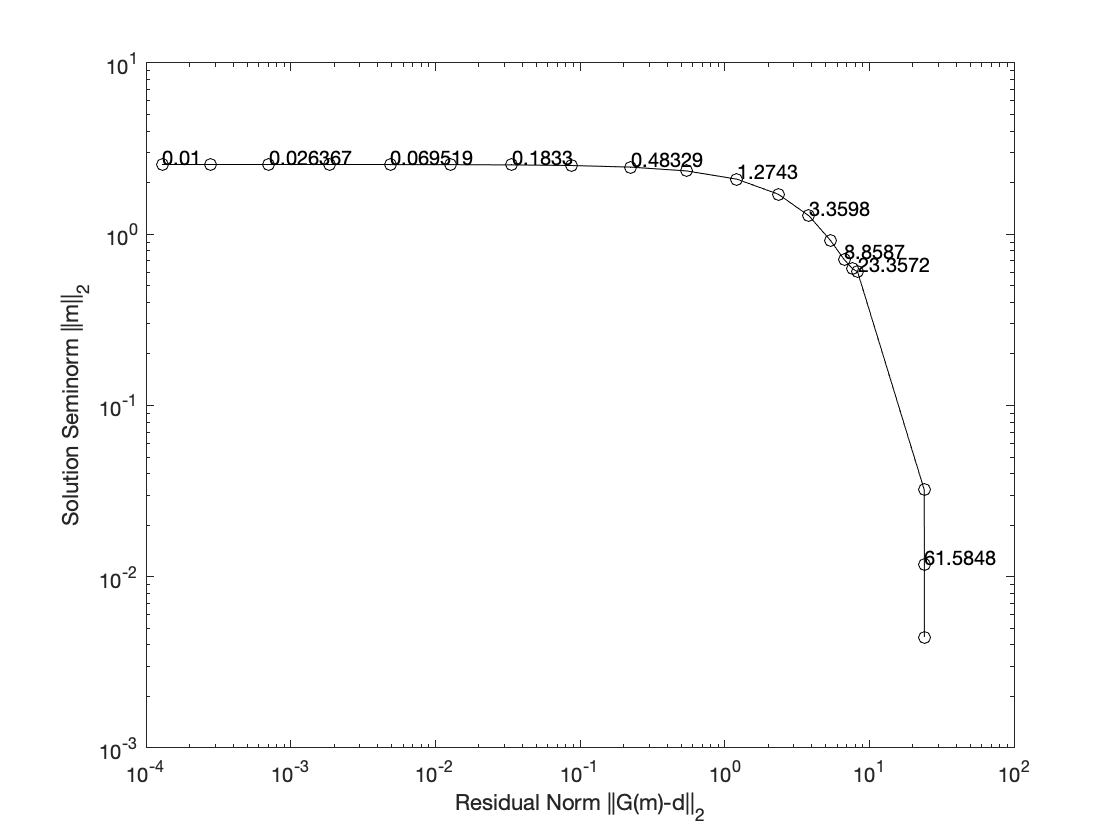


alphas = logspace(-2,2,20);

Nalpha = length(alphas);

misfit = zeros(Nalpha,1);
mnorm = zeros(Nalpha,1);

Iter = zeros(Nalpha,1);

L = eye(2);
piter = 0;

for alpha = alphas
    
    piter = piter+1;
   
    mes = m0;
    r = norm(m0) + 0.1;
    itk = 0;
    
    % start the iterative model loop

    while(r > tol)
        
        itk = itk + 1;
        
        Ym = funy(mes);
        J = Jacb2(mes);
        
        dm = -(J'*J + alpha^2*(L'*L))\(J'*Ym + alpha^2*(L'*L)*mes);
        
        %model update
        
        mes = mes + dm;
        r = norm(dm);

    end

    Iter(piter) = itk;
    
    misfit(piter) = norm(Ym);
    mnorm(piter) = norm(mes);
    
end

%L-curve figure
figure(2)
clf
loglog(misfit,mnorm,'ok-')

xlabel('Residual Norm ||G(m)-d||_2')
ylabel('Solution Seminorm ||m||_2')
hold on
%plot the discrepancy principle line
%loglog([sigma*sqrt(ml),sigma*sqrt(ml)],[1e-3,10],'b--')

for i=1:2:Nalpha
  %text(misfit1(i),mnorm1(i),[' ',num2str(sqrt(alphas(i)))]);
  text(misfit(i),mnorm(i),['',num2str(alphas(i))],'VerticalAlignment','baseline');
end

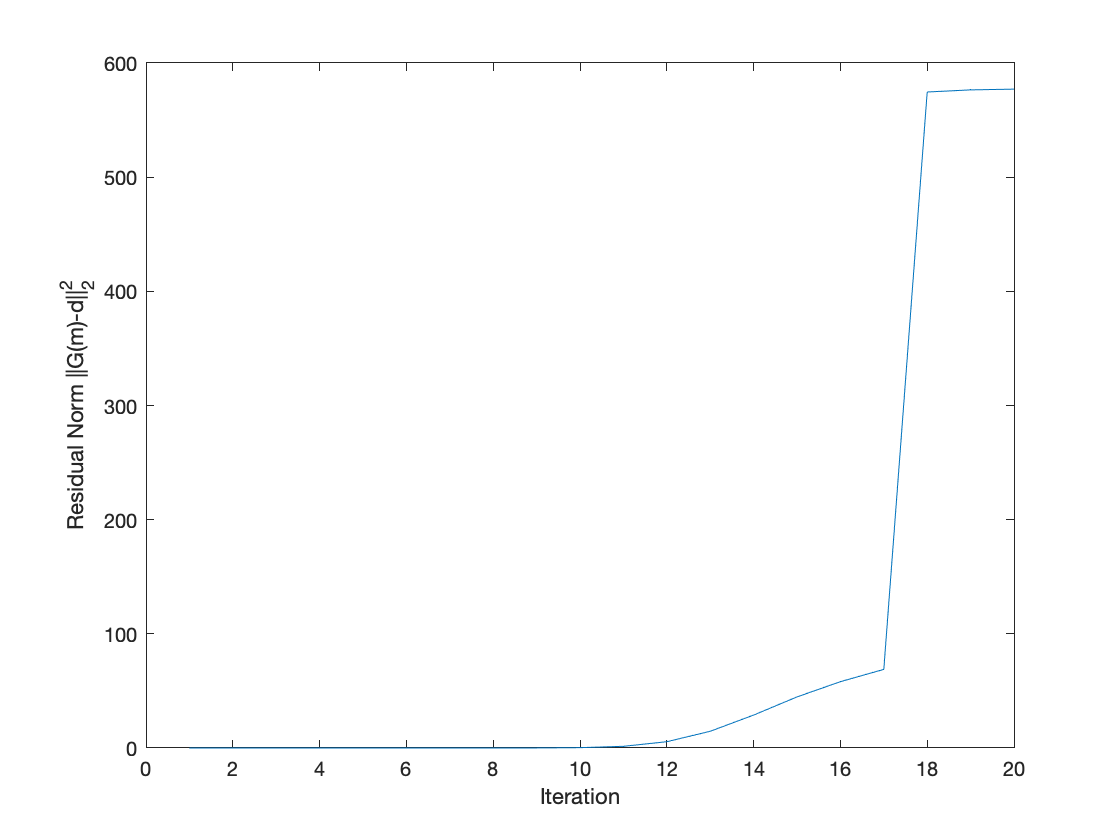


%text(sigma*sqrt(ml),0.005,'  \delta = 0.3354')

%this figure shows the residual stats for each iteration and alpha value
figure(3)
clf
plot(misfit.^2)
xlabel('Iteration')
ylabel('Residual Norm ||G(m)-d||_2^2')

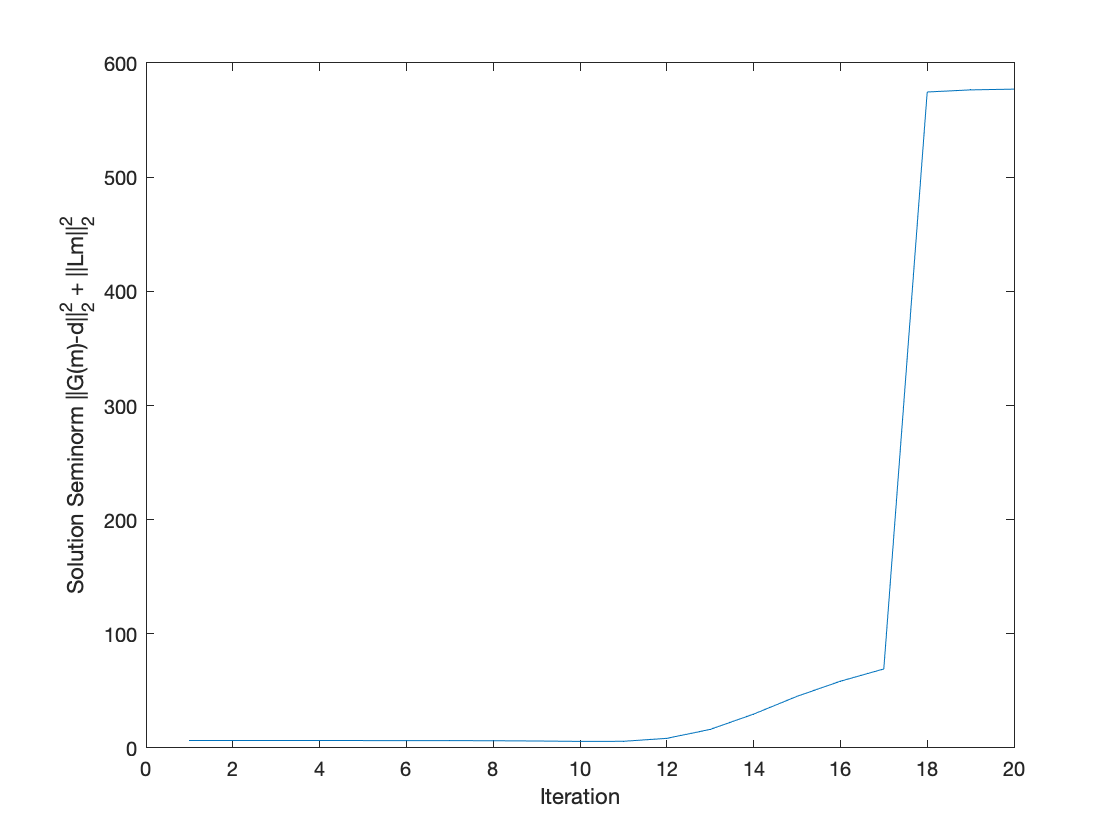

%this figure shows the seminorm statistics for each iteration and alpha value
figure(4)
res = misfit.^2 + mnorm.^2;
plot(res)
xlabel('Iteration')
ylabel('Solution Seminorm ||G(m)-d||_2^2 + ||Lm||_2^2')

delta = sigma*sqrt(ml);
moccam = occam(L,Yt,m0,delta)

moccam =     2.4809
    0.2627


function [m, iter] = Levenberg_Marquardt(m0,alpha,tol)
    
    global Jacb2; 
    global funy;
    
    Ja = @(m) Jacb2(m);
    
    n = length(m0);   % number of paramter
    iter = 0;         % iterations counter
    r = norm(m0) + 1;     % compute the norm of the error
    
    while(r > tol)
        
        Jm = Ja(m0);
        
        Ym = funy(m0);
        
        Dm = -(Jm'*Jm + alpha^2*eye(n))\(Jm'*Ym);
        
        m0 = m0 + Dm;
        r = norm(Dm);  % compute the norm of the error

        iter = iter + 1;
        
    end
    m = m0;
end    
